# Get path

currentpath = pwd;
currentfolder = strsplit(currentpath,filesep);
while ((~strcmp(currentfolder{end}, 'EMS-aircraft')) && ...
        (~strcmp(currentfolder{end}, 'EMS-aircraft-main')) && ...
        ~isempty(currentfolder{end}))
currentpath = fileparts(currentpath);
currentfolder = strsplit(currentpath,filesep);
end
projectpath = currentpath;
addpath(genpath(projectpath));
folder_data= strcat(projectpath,'\Data');

# Load

% load load_to_test
% old_w = str2double(to_try.power)';
% old_t = str2double(to_try.time)'/2;
% t = 0:1e-3:old_t(end);
% w = fixpt_interp1(old_t,old_w,t,float('single'),[],float('single'),...
%     [],'Floor');

load load_to_train
[cell_t,cell_w] = data_to_use(XTrain,YTrain);
classes = categories(YTrain{1});

t = cell_t{1};
w = cell_w{1};

# Model + set the init value

load_system(strcat(projectpath,'\Main\powertrain.slx'));
model = strcat(projectpath,'\Main\powertrain.slx');
Ts = 1e-3;

for i = 1:length(cell_t)
    t = cell_t{i};
    w = cell_w{i};
    SimTime = t(end); % Max simulation time
    
    % set the initial battery SOC
    SOC_init = 80;
    set_param('powertrain/Battery','SOC', string(SOC_init));
    EMS_block  = 'powertrain/EMS';
    warning('off','all');
    
    tic
    set_param(EMS_block,'ems','ECMS');
    ECMS = sim(model,'StartTime','0','StopTime',num2str(SimTime), 'SaveOutput','on');
    ECMS.real_time_sim = toc;
    ECMS.real_time_sim
    save_(ECMS,folder_data,SOC_init,'ECMS_' + convertCharsToStrings(classes{i}),SimTime);
end

Found algebraic loop containing: 
powertrain/PEMFC matfunc V2/MATLAB Function
powertrain/PEMFC matfunc V2/Product1 (algebraic variable)
This algebraic loop may be resolved when the subsystem option 'Minimize algebraic loop occurrences' is selected on some or all of the atomic and enabled subsystems in this algebraic loop


ans = 319.3384

Found algebraic loop containing: 
powertrain/PEMFC matfunc V2/MATLAB Function
powertrain/PEMFC matfunc V2/Product1 (algebraic variable)
This algebraic loop may be resolved when the subsystem option 'Minimize algebraic loop occurrences' is selected on some or all of the atomic and enabled subsystems in this algebraic loop


ans = 367.5690

Found algebraic loop containing: 
powertrain/PEMFC matfunc V2/MATLAB Function
powertrain/PEMFC matfunc V2/Product1 (algebraic variable)
This algebraic loop may be resolved when the subsystem option 'Minimize algebraic loop occurrences' is selected on some or all of the atomic and enabled subsystems in this algebraic loop


ans = 268.8530

Found algebraic loop containing: 
powertrain/PEMFC matfunc V2/MATLAB Function
powertrain/PEMFC matfunc V2/Product1 (algebraic variable)
This algebraic loop may be resolved when the subsystem option 'Minimize algebraic loop occurrences' is selected on some or all of the atomic and enabled subsystems in this algebraic loop


ans = 324.2868

# Data from ECMS

for i = 1:length(classes)
    session = convertCharsToStrings(classes{i});
    fileName = strcat('B',int2str(SOC_init),'_ECMS_',session);
    load(strcat(folder_data,'\',fileName,'.mat'));
    ECMS = out;
    
    % in1 = (ECMS.LOAD.signals.values(:,3) - ECMS.LOAD.signals.values(:,1) .* ECMS.PV.signals.values(:,5))/1500;
    % in2 = ECMS.Batt.signals.values(:,6)./100;
    %
    % out1 = ECMS.FC.signals.values(:,4).*ECMS.FC.signals.values(:,1)/1100;
    % trainingData = [in1, in2, out1];
    
    trainingData = [ECMS.to_anfis.signal1.Data  ECMS.to_anfis.signal2.Data  ECMS.to_anfis.signal3.Data];
    
    
    genOpt = genfisOptions('GridPartition');
    genOpt.NumMembershipFunctions = [10 10];
    genOpt.InputMembershipFunctionType = 'gaussmf';
    genOpt.OutputMembershipFunctionType = 'linear';
    inFIS = genfis(trainingData(:,1:2),trainingData(:,3),genOpt);
    opt = anfisOptions('InitialFIS',inFIS,'EpochNumber',2);
    opt.DisplayANFISInformation = 0;
    opt.DisplayErrorValues = 0;
    opt.DisplayStepSize = 0;
    opt.DisplayFinalResults = 0;
    [fis,trainError] = anfis(trainingData,opt);
    fisRMSE = min(trainError)
    writeFIS(fis,fileName)
end

fisRMSE = 0.0170

fisRMSE = 0.0194

fisRMSE = 8.8803e-08

fisRMSE = 0.0309

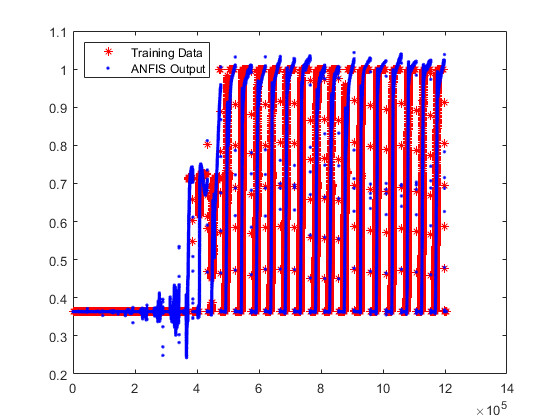

figure
anfisOutput = evalfis(fis,trainingData(:,1:2));
tt = 1:length(trainingData(:,3));
plot(tt,trainingData(:,3),'*r',tt,anfisOutput,'.b')
legend('Training Data','ANFIS Output','Location','NorthWest')